## PART 1: KINEMATICS

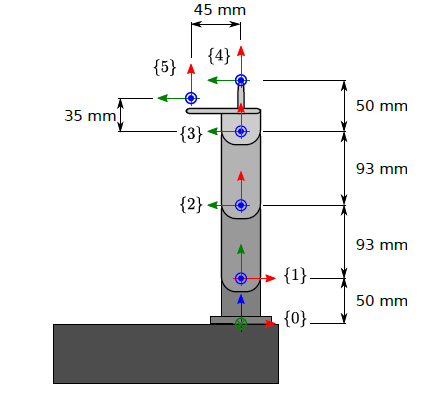

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms theta0 theta1 theta2 theta3 

% Rotation matrices
R_x_90 = [1 0 0;
          0 0 -1;
          0 1 0];
R_z_90 = [0 -1 0;
          1 0 0;
          0 0 1];
R_z_th0 = [cos(theta0) -sin(theta0) 0;
       sin(theta0) cos(theta0) 0;
       0 0 1];
R_z_th1 = [cos(theta1) -sin(theta1) 0;
       sin(theta1) cos(theta1) 0;
       0 0 1];
R_z_th2 = [cos(theta2) -sin(theta2) 0;
       sin(theta2) cos(theta2) 0;
       0 0 1];
R_z_th3 = [cos(theta3) -sin(theta3) 0;
       sin(theta3) cos(theta3) 0;
       0 0 1];

R01 = R_x_90*R_z_th0;
R12 = R_z_90*R_z_th1;
R23 = R_z_th2;
R34 = R_z_th3;
R35 = R_z_th3;

% Translation matrices
t01 = [0 0 L01]';
t12 = [L12 0 0]';
t23 = [L23 0 0]';
t34 = [0 0 L34]';
t35 = [0 0 L35]';

% {0} -> {1}
T01 = [R01 t01;
        zeros(1,3) 1];

% {1} -> {2}
T12 = [R12 t12;
       zeros(1,3) 1];

% {2} -> {3}
T23 = [R23 t23;
       zeros(1,3) 1];

% {3} -> {4}
T34 = [R34 t34;
       zeros(1,3) 1];

% {3} -> {5}
T35 = [R35 t35;
       zeros(1,3) 1];

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1}-\cos\left(\theta_{3}\right)\,\sigma_{3} & 0 & 93\,\cos\left(\theta_{0}\right)-93\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)-93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\\ 0 & 0 & -1 & -50\\ \cos\left(\theta_{3}\right)\,\sigma_{3}-\sigma_{1} & \sigma_{2} & 0 & 93\,\sin\left(\theta_{0}\right)+93\,\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-93\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)\\ \sigma_{2}=-\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)-\sin\left(\theta_{3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)-\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right) \end{array}$$


% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1}-\cos\left(\theta_{3}\right)\,\sigma_{3} & 0 & 93\,\cos\left(\theta_{0}\right)-93\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)-93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\\ 0 & 0 & -1 & -35\\ \cos\left(\theta_{3}\right)\,\sigma_{3}-\sigma_{1} & \sigma_{2} & 0 & 93\,\sin\left(\theta_{0}\right)+93\,\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-93\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)\\ \sigma_{2}=-\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)-\sin\left(\theta_{3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)-\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right) \end{array}$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

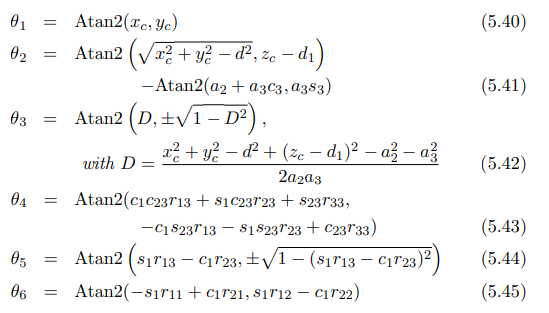

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



theta0 = atan2(xc,yc);

theta2 = atan2(D, sqrt(1-D^2));

theta1 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(theta3), L23*sin(theta3));

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





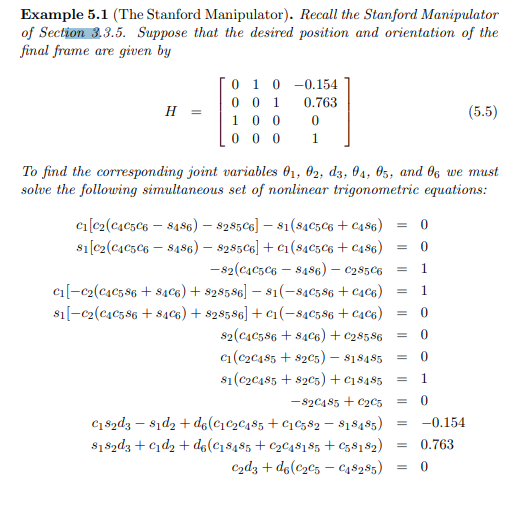

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

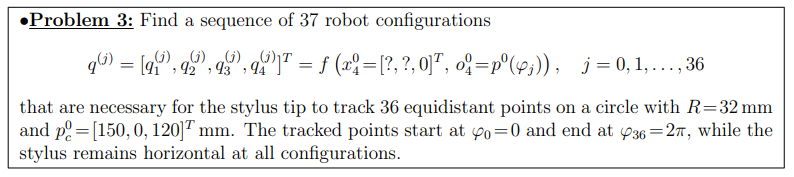


% origin of the circle to be traced
xc = 150;
yc = 100;
zc = 100;

angles = 0:2*pi/36:2*pi % this is the phi angle reported in the previous line

angles =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708    1.7453    1.9199    2.0944    2.2689    2.4435    2.6180    2.7925    2.9671    3.1416    3.3161    3.4907    3.6652    3.8397    4.0143    4.1888    4.3633    4.5379    4.7124    4.8869    5.0615    5.2360    5.4105    5.5851    5.7596    5.9341    6.1087    6.2832




dy = cos(angles)*16;
dz = sin(angles)*16;

x = xc*ones(1,length(angles))

x =    150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150


y = yc + dy

y =   116.0000  115.7569  115.0351  113.8564  112.2567  110.2846  108.0000  105.4723  102.7784  100.0000   97.2216   94.5277   92.0000   89.7154   87.7433   86.1436   84.9649   84.2431   84.0000   84.2431   84.9649   86.1436   87.7433   89.7154   92.0000   94.5277   97.2216  100.0000  102.7784  105.4723  108.0000  110.2846  112.2567  113.8564  115.0351  115.7569  116.0000


z = zc + dz

z =   100.0000  102.7784  105.4723  108.0000  110.2846  112.2567  113.8564  115.0351  115.7569  116.0000  115.7569  115.0351  113.8564  112.2567  110.2846  108.0000  105.4723  102.7784  100.0000   97.2216   94.5277   92.0000   89.7154   87.7433   86.1436   84.9649   84.2431   84.0000   84.2431   84.9649   86.1436   87.7433   89.7154   92.0000   94.5277   97.2216  100.0000





% Taras insert magic here. Please transform thew set of
% coordinates[x,y,z](37 points of each) into a set of coordinates

% Stylus always parallel to the ground
x04 = [0, 0, 1];
pos = [x; y; z];

for p = 1:size(pos,2)
    [t1(p),t2(p),t3(p),t4(p)] = invKinematics(x04, pos(:,p));
end

Angles:
 theta1: 
    0.6583

 theta2: 
    0.8279

 theta3: 
   63.5604

 theta4: 
  -62.8176

Angles:
 theta1: 
    0.6573

 theta2: 
    0.3080

 theta3: 
   62.4991

 theta4: 
  -61.2364

Angles:
 theta1: 
    0.6542

 theta2: 
   -0.2294

 theta3: 
   61.4047

 theta4: 
  -59.6044

Angles:
 theta1: 
    0.6493

 theta2: 
   -0.7646

 theta3: 
   60.3169

 theta4: 
  -57.9815

Angles:
 theta1: 
    0.6425

 theta2: 
    1.8666

 theta3: 
   59.2813

 theta4: 
  -59.5770

Angles:
 theta1: 
    0.6340

 theta2: 
    1.4048

 theta3: 
   58.3456

 theta4: 
  -58.1796

Angles:
 theta1: 
    0.6240

 theta2: 
    1.0154

 theta3: 
   57.5572

 theta4: 
  -57.0018

Angles:
 theta1: 
    0.6128

 theta2: 
    0.7197

 theta3: 
   56.9589

 theta4: 
  -56.1078

Angles:
 theta1: 
    0.6007

 theta2: 
    0.5348

 theta3: 
   56.5851

 theta4: 
  -55.5491

Angles:
 theta1: 
    0.5880

 theta2: 
    0.4719

 theta3: 
   56.4579

 theta4: 
  -55.3590

Angles:
 theta1: 
    0.5751

 theta2: 




%t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));


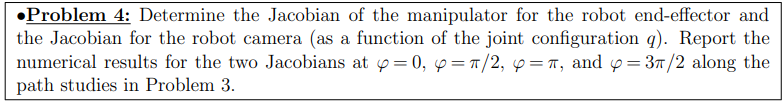

% if you need help figuring out the angles contact Palli
clc
disp("helloo")

helloo


phi = [0 pi/2 pi 3*pi/2];
%phi = pi;
dy = cos(phi)*16;
dz = sin(phi)*16;

x = zeros(1,length(phi));
y = yc + dy;
z = zc + dz;

[t1,t2,t3] = theta(x,y,z);
t4 = ones(1,length(x)).*(pi-t1-t2-t3);

for i = 1:1%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34)
end

T04 =     0.7293    0.6842         0  197.2877
   -0.6842    0.7293         0  -97.8421
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.7293    0.6842         0  160.8235
   -0.6842    0.7293         0  -63.6316
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.7293    0.6842         0   93.0000
   -0.6842    0.7293         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 =      1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 =      0     0     1


o1 =      0     0    50


z2 =      0     0     1


o2 =     93     0    50


z3 =      0     0     1


o3 =   160.8235  -63.6316   50.0000


o4 =   197.2877  -97.8421   50.0000


J0 =      0
     0
     1
     0
     0
     0


J1 =    97.8421
  197.2877
         0
         0
         0
    1.0000


J2 =    97.8421
  104.2877
         0
         0
         0
    1.0000


J3 =    34.2105
   36.4642
         0
         0
         0
    1.0000


J =          0   97.8421   97.8421   34.2105
         0  197.2877  104.2877   36.4642
    1.0000         0         0         0
         0         0         0         0
         0         0         0         0
         0    1.0000    1.0000    1.0000


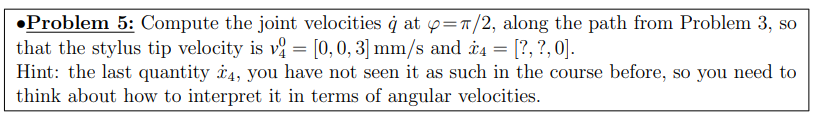

%[T01_old, T12_old, T23_old, T34_old, T35_old] = T_finder(t1(1),t2(1),t3(1),t4(1));

for i = 2:3%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));

    T04=T01*T12*T23*T34
    T03=T01*T12*T23
    T02=T01*T12
    
    o4 = [T04(1,4) T04(2,4) T04(3,4)];

    dt1 = t1(i) - t1(i-1);
    dt2 = t2(i) - t2(i-1);
    dt3 = t3(i) - t3(i-1);
    dt4 = t4(i) - t4(i-1);

    k1 = [T01(1,4); T01(2,4); T01(3,4)];
    k1 = k1*(1/max(k1));
    k2 = [T12(1,4); T12(2,4); T12(3,4)];
    k2 = k2*(1/max(k2));
    k3 = [T23(1,4); T23(2,4); T23(3,4)];
    k3 = k3*(1/max(k3));
    k4 = [T34(1,4); T34(2,4); T34(3,4)];
    k4 = k4*(1/max(k4));

    w01 = dt1*k1;
    w12 = dt2*k2;
    w23 = dt3*k3;
    w34 = dt4*k4;

    R01 = [T01(1,1) T01(1,2) T01(1,3);T01(2,1) T01(2,2) T01(2,3);T01(3,1) T01(3,2) T01(3,3)];
    R02 = [T02(1,1) T02(1,2) T02(1,3);T02(2,1) T02(2,2) T02(2,3);T02(3,1) T02(3,2) T02(3,3)];
    R03 = [T03(1,1) T03(1,2) T03(1,3);T03(2,1) T03(2,2) T03(2,3);T03(3,1) T03(3,2) T03(3,3)];
    R04 = [T04(1,1) T04(1,2) T04(1,3);T04(2,1) T04(2,2) T04(2,3);T04(3,1) T04(3,2) T04(3,3)];

    w04 = w01 + R01*w12 + R02*w23 + R03*w34;

    v04 = cross(w04,o4)
    




end

T04 =     0.9529   -0.3032         0  229.2686
    0.2400    0.7544   -0.6109   34.3250
    0.1852    0.5822    0.7917   76.4890
         0         0         0    1.0000


T03 =     0.9529   -0.3032         0  181.6222
    0.2400    0.7544   -0.6109   22.3232
    0.1852    0.5822    0.7917   67.2271
         0         0         0    1.0000


T02 =     0.9529   -0.3032         0   93.0000
    0.2400    0.7544   -0.6109         0
    0.1852    0.5822    0.7917   50.0000
         0         0         0    1.0000


v04 =     6.2744   23.7183  -29.4505


T04 =     0.9738    0.2274         0  232.2533
   -0.1805    0.7727   -0.6085  -25.8047
   -0.1384    0.5926    0.7935   30.2104
         0         0         0    1.0000


T03 =     0.9738    0.2274         0  183.5634
   -0.1805    0.7727   -0.6085  -16.7820
   -0.1384    0.5926    0.7935   37.1298
         0         0         0    1.0000


T02 =     0.9738    0.2274         0   93.0000
   -0.1805    0.7727   -0.6085         0
   -0.1384    0.5926    0.7935   50.0000
         0         0         0    1.0000


v04 =    -4.9273  -17.5515   22.8888


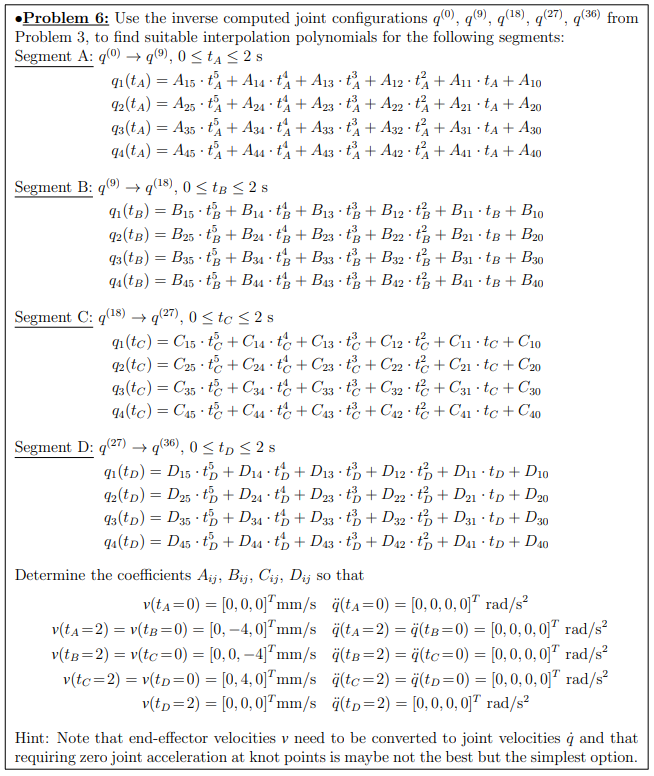

load("t1.mat");
load("t2.mat");
load("t3.mat");
load("t4.mat");
tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval
MatrixofQ = [t1(1) t1(10) t1(19) t1(28) t1(37);
             t2(1) t2(10) t2(19) t2(28) t2(37);
             t3(1) t3(10) t3(19) t3(28) t3(37);
             t4(1) t4(10) t4(19) t4(28) t4(37)];%t(1), t(10), t(19), t(28), t(37) is
                                                %relative to q(0), q(9), q(18), q(27), q(36)
V0 = [0;0;0;0;0;0];
VA = [0;-4;0;0;0;0];
VB = [0;0;-4;0;0;0];
VC = [0;4;0;0;0;0];
VD = [0;0;0;0;0;0];
%vectors of end-effffector velocities v 
JA = getJacobian(10);

o04 =  -173.2162
         0
   48.2785


o14 =  -173.2162
         0
   48.2785


o24 =   -89.1045
  148.5503
         0


o34 =    92.3358
 -234.9552
         0


J =          0  -48.2785         0         0
 -173.2162         0         0         0
         0 -173.2162  -89.1045   92.3358
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


JB = getJacobian(19);

o04 =  -163.2115
         0
  -28.8473


o14 =  -163.2115
         0
  -28.8473


o24 =  -123.0441
  133.0979
         0


o34 =   123.1004
 -267.9202
         0


J =          0   28.8473         0         0
 -163.2115         0         0         0
         0 -163.2115 -123.0441  123.1004
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


JC = getJacobian(28);

o04 =  -167.1672
         0
   27.0025


o14 =  -167.1672
         0
   27.0025


o24 =  -111.6978
  126.4807
         0


o34 =   106.1632
 -248.9397
         0


J =          0  -27.0025         0         0
 -167.1672         0         0         0
         0 -167.1672 -111.6978  106.1632
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


JD = getJacobian(37);

o04 =  -156.6301
         0
   91.1506


o14 =  -156.6301
         0
   91.1506


o24 =   -77.2531
  142.3317
         0


o34 =    78.2293
 -220.6250
         0


J =          0  -91.1506         0         0
 -156.6301         0         0         0
         0 -156.6301  -77.2531   78.2293
         0         0         0         0
         0   -1.0000   -1.0000   -1.0000
    1.0000         0         0         0


%jaconbian matrix for calculating joint velocities ˙q
v0=0;
I=eye(4);
b=[0; 0; 0; 0];
JAp=inv(JA'*JA)*JA';
JBp=inv(JB'*JB)*JB';
JCp=inv(JC'*JC)*JC';
JDp=inv(JD'*JD)*JD';
vA=JAp*VA+(I-JAp*JA)*b;
vB=JBp*VB+(I-JBp*JB)*b;
vC=JCp*VC+(I-JCp*JC)*b;
vD=JDp*VD+(I-JDp*JD)*b;
%Calculation of joint velocities ˙q
ain = 0;
aout = 0;
%acceleration is always 0

A1 = getConstant(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1),ain,aout);
A2 = getConstant(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1),ain,aout);
A3 = getConstant(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1),ain,aout);
A4 = getConstant(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1),ain,aout);
A = [A1;A2;A3;A4];

B1 = getConstant(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1),ain,aout);
B2 = getConstant(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1),ain,aout);
B3 = getConstant(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1),ain,aout);
B4 = getConstant(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1),ain,aout);
B = [B1;B2;B3;B4];

C1 = getConstant(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1),ain,aout);
C2 = getConstant(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1),ain,aout);
C3 = getConstant(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1),ain,aout);
C4 = getConstant(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1),ain,aout);
C = [C1;C2;C3;C4];

D1 = getConstant(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1),ain,aout);

D2 = getConstant(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1),ain,aout);
D3 = getConstant(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1),ain,aout);
D4 = getConstant(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1),ain,aout);
D = [D1;D2;D3;D4];
%Calculation of Coefficients in Interpolation Functions

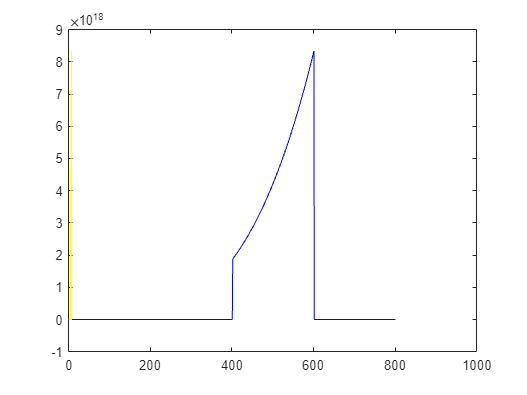

x = 0:0.01:8;
q1A = A1(6) * x.^5 + A1(5) * x.^4 + A1(4) * x.^3 + A1(3) * x.^2 + A1(2) * x + A1(1);
q2A = A2(6) * x.^5 + A2(5) * x.^4 + A2(4) * x.^3 + A2(3) * x.^2 + A2(2) * x + A2(1);
q3A = A3(6) * x.^5 + A3(5) * x.^4 + A3(4) * x.^3 + A3(3) * x.^2 + A3(2) * x + A3(1);
q4A = A4(6) * x.^5 + A4(5) * x.^4 + A4(4) * x.^3 + A4(3) * x.^2 + A4(2) * x + A4(1);

q1B = B1(6) * x.^5 + B1(5) * x.^4 + B1(4) * x.^3 + B1(3) * x.^2 + B1(2) * x + B1(1);
q2B = B2(6) * x.^5 + B2(5) * x.^4 + B2(4) * x.^3 + B2(3) * x.^2 + B2(2) * x + B2(1);
q3B = B3(6) * x.^5 + B3(5) * x.^4 + B3(4) * x.^3 + B3(3) * x.^2 + B3(2) * x + B3(1);
q4B = B4(6) * x.^5 + B4(5) * x.^4 + B4(4) * x.^3 + B4(3) * x.^2 + B4(2) * x + B4(1);

q1C = C1(6) * x.^5 + C1(5) * x.^4 + C1(4) * x.^3 + C1(3) * x.^2 + C1(2) * x + C1(1);
q2C = C2(6) * x.^5 + C2(5) * x.^4 + C2(4) * x.^3 + C2(3) * x.^2 + C2(2) * x + C2(1);
q3C = C3(6) * x.^5 + C3(5) * x.^4 + C3(4) * x.^3 + C3(3) * x.^2 + C3(2) * x + C3(1);
q4C = C4(6) * x.^5 + C4(5) * x.^4 + C4(4) * x.^3 + C4(3) * x.^2 + C4(2) * x + C4(1);

q1D = D1(6) * x.^5 + D1(5) * x.^4 + D1(4) * x.^3 + D1(3) * x.^2 + D1(2) * x + D1(1);
q2D = D2(6) * x.^5 + D2(5) * x.^4 + D2(4) * x.^3 + D2(3) * x.^2 + D2(2) * x + D2(1);
q3D = D3(6) * x.^5 + D3(5) * x.^4 + D3(4) * x.^3 + D3(3) * x.^2 + D3(2) * x + D3(1);
q4D = D4(6) * x.^5 + D4(5) * x.^4 + D4(4) * x.^3 + D4(3) * x.^2 + D4(2) * x + D4(1);
figure; % Create a new figure window
y1 = q1A.*(x>=0&x<=2) + q1B.*(x>2&x<=4) + q1C.*(x>4&x<=6) + q1D.*(x>6&x<=8);
plot(y1, 'b');
hold on
y2 = q2A.*(x>=0&x<=2) + q2B.*(x>2&x<=4) + q2C.*(x>4&x<=6) + q2D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q3A.*(x>=0&x<=2) + q3B.*(x>2&x<=4) + q3C.*(x>4&x<=6) + q3D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q4A.*(x>=0&x<=2) + q4B.*(x>2&x<=4) + q4C.*(x>4&x<=6) + q4D.*(x>6&x<=8);
plot(x, y1, 'y'); 

%%seven knot points
A71 = getConstant7(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1),ain,aout);
A72 = getConstant7(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1),ain,aout);
A73 = getConstant7(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1),ain,aout);
A74 = getConstant7(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1),ain,aout);
A7 = [A71 A72 A73 A74];
 
B71 = getConstant7(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1),ain,aout);
B72 = getConstant7(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1),ain,aout);
B73 = getConstant7(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1),ain,aout);
B74 = getConstant7(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1),ain,aout);
B7 = [B71 B72 B73 B74];

C71 = getConstant7(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1),ain,aout);
C72 = getConstant7(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1),ain,aout);
C73 = getConstant7(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1),ain,aout);
C74 = getConstant7(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1),ain,aout);
C7 = [C71 C72 C73 C74];

D71 = getConstant7(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1),ain,aout);

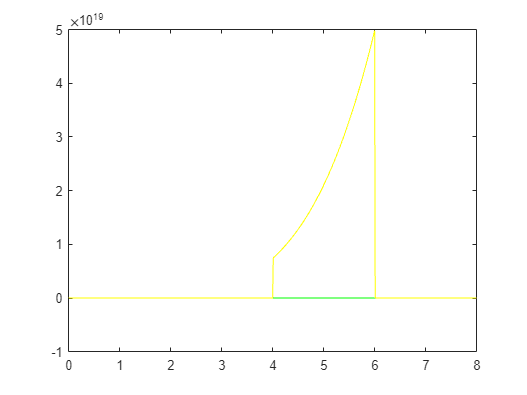

D72 = getConstant7(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1),ain,aout);
D73 = getConstant7(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1),ain,aout);
D74 = getConstant7(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1),ain,aout);
D7 = [D71 D72 D73 D74];

x = 0:0.01:8;
q71A = A71(8) * x.^7 + A71(7) * x.^6 + A71(6) * x.^5 + A71(5) * x.^4 + A71(4) * x.^3 + A71(3) * x.^2 + A71(2) * x + A71(1);
q72A = A72(8) * x.^7 + A72(7) * x.^6 + A72(6) * x.^5 + A72(5) * x.^4 + A72(4) * x.^3 + A72(3) * x.^2 + A72(2) * x + A72(1);
q73A = A73(8) * x.^7 + A73(7) * x.^6 + A73(6) * x.^5 + A73(5) * x.^4 + A73(4) * x.^3 + A73(3) * x.^2 + A73(2) * x + A73(1);
q74A = A74(8) * x.^7 + A74(7) * x.^6 + A74(6) * x.^5 + A74(5) * x.^4 + A74(4) * x.^3 + A74(3) * x.^2 + A74(2) * x + A74(1);

q71B = B71(8) * x.^7 + B71(7) * x.^6 + B71(6) * x.^5 + B71(5) * x.^4 + B71(4) * x.^3 + B71(3) * x.^2 + B71(2) * x + B71(1);
q72B = B72(8) * x.^7 + B72(7) * x.^6 + B72(6) * x.^5 + B72(5) * x.^4 + B72(4) * x.^3 + B72(3) * x.^2 + B72(2) * x + B72(1);
q73B = B73(8) * x.^7 + B73(7) * x.^6 + B73(6) * x.^5 + B73(5) * x.^4 + B73(4) * x.^3 + B73(3) * x.^2 + B73(2) * x + B73(1);
q74B = B74(8) * x.^7 + B74(7) * x.^6 + B74(6) * x.^5 + B74(5) * x.^4 + B74(4) * x.^3 + B74(3) * x.^2 + B74(2) * x + B74(1);

q71C = C71(8) * x.^7 + C71(7) * x.^6 + C71(6) * x.^5 + C71(5) * x.^4 + C71(4) * x.^3 + C71(3) * x.^2 + C71(2) * x + C71(1);
q72C = C72(8) * x.^7 + C72(7) * x.^6 + C72(6) * x.^5 + C72(5) * x.^4 + C72(4) * x.^3 + C72(3) * x.^2 + C72(2) * x + C72(1);
q73C = C73(8) * x.^7 + C73(7) * x.^6 + C73(6) * x.^5 + C73(5) * x.^4 + C73(4) * x.^3 + C73(3) * x.^2 + C73(2) * x + C73(1);
q74C = C74(8) * x.^7 + C74(7) * x.^6 + C74(6) * x.^5 + C74(5) * x.^4 + C74(4) * x.^3 + C74(3) * x.^2 + C74(2) * x + C74(1);

q71D = D71(8) * x.^7 + D71(7) * x.^6 + D71(6) * x.^5 + D71(5) * x.^4 + D71(4) * x.^3 + D71(3) * x.^2 + D71(2) * x + D71(1);
q72D = D72(8) * x.^7 + D72(7) * x.^6 + D72(6) * x.^5 + D72(5) * x.^4 + D72(4) * x.^3 + D72(3) * x.^2 + D72(2) * x + D72(1);
q73D = D73(8) * x.^7 + D73(7) * x.^6 + D73(6) * x.^5 + D73(5) * x.^4 + D73(4) * x.^3 + D73(3) * x.^2 + D73(2) * x + D73(1);
q74D = D74(8) * x.^7 + D74(7) * x.^6 + D74(6) * x.^5 + D74(5) * x.^4 + D74(4) * x.^3 + D74(3) * x.^2 + D74(2) * x + D74(1);
figure; % Create a new figure window
y1 = q71A.*(x>=0&x<=2) + q71B.*(x>2&x<=4) + q71C.*(x>4&x<=6) + q71D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q72A.*(x>=0&x<=2) + q72B.*(x>2&x<=4) + q72C.*(x>4&x<=6) + q72D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q73A.*(x>=0&x<=2) + q73B.*(x>2&x<=4) + q73C.*(x>4&x<=6) + q73D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q74A.*(x>=0&x<=2) + q74B.*(x>2&x<=4) + q74C.*(x>4&x<=6) + q74D.*(x>6&x<=8);
plot(x, y1, 'y'); 

%%three knot points
A31 = getConstant3(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1));
A32 = getConstant3(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1));
A33 = getConstant3(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1));
A34 = getConstant3(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1));
A3 = [A31 A32 A33 A34];
 
B31 = getConstant3(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1));
B32 = getConstant3(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1));
B33 = getConstant3(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1));
B34 = getConstant3(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1));
B3 = [B31 B32 B33 B34];

C31 = getConstant3(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1));
C32 = getConstant3(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1));
C33 = getConstant3(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1));
C34 = getConstant3(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1));
C3 = [C31 C32 C33 C34];

D31 = getConstant3(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1));

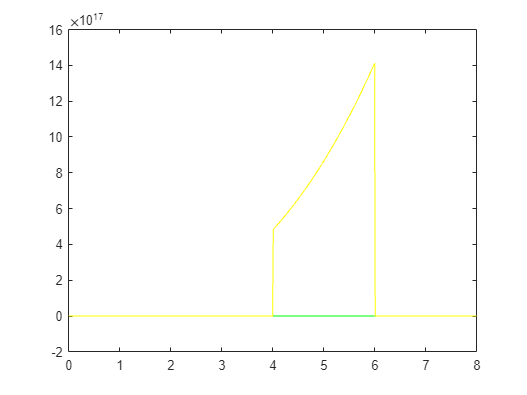

D32 = getConstant3(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1));
D33 = getConstant3(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1));
D34 = getConstant3(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1));
D3 = [D31 D32 D33 D34];

x = 0:0.01:8;
q31A = A31(4) * x.^3 + A31(3) * x.^2 + A31(2) * x + A31(1);
q32A = A32(4) * x.^3 + A32(3) * x.^2 + A32(2) * x + A32(1);
q33A = A33(4) * x.^3 + A33(3) * x.^2 + A33(2) * x + A33(1);
q34A = A34(4) * x.^3 + A34(3) * x.^2 + A34(2) * x + A34(1);

q31B = B31(4) * x.^3 + B31(3) * x.^2 + B31(2) * x + B31(1);
q32B = B32(4) * x.^3 + B32(3) * x.^2 + B32(2) * x + B32(1);
q33B = B33(4) * x.^3 + B33(3) * x.^2 + B33(2) * x + B33(1);
q34B = B34(4) * x.^3 + B34(3) * x.^2 + B34(2) * x + B34(1);

q31C = C31(4) * x.^3 + C31(3) * x.^2 + C31(2) * x + C31(1);
q32C = C32(4) * x.^3 + C32(3) * x.^2 + C32(2) * x + C32(1);
q33C = C33(4) * x.^3 + C33(3) * x.^2 + C33(2) * x + C33(1);
q34C = C34(4) * x.^3 + C34(3) * x.^2 + C34(2) * x + C34(1);

q31D = D31(4) * x.^3 + D31(3) * x.^2 + D31(2) * x + D31(1);
q32D = D32(4) * x.^3 + D32(3) * x.^2 + D32(2) * x + D32(1);
q33D = D33(4) * x.^3 + D33(3) * x.^2 + D33(2) * x + D33(1);
q34D = D34(4) * x.^3 + D34(3) * x.^2 + D34(2) * x + D34(1);
figure; % Create a new figure window
y1 = q31A.*(x>=0&x<=2) + q31B.*(x>2&x<=4) + q31C.*(x>4&x<=6) + q31D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q32A.*(x>=0&x<=2) + q32B.*(x>2&x<=4) + q32C.*(x>4&x<=6) + q32D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q33A.*(x>=0&x<=2) + q33B.*(x>2&x<=4) + q33C.*(x>4&x<=6) + q33D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q34A.*(x>=0&x<=2) + q34B.*(x>2&x<=4) + q34C.*(x>4&x<=6) + q34D.*(x>6&x<=8);
plot(x, y1, 'y'); 

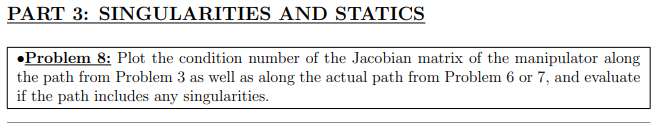


k=zeros(1,length(t1))

k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34); % Get jacobian at a given point
    J = [J(1:3,:);J(6,:)] ;% Remove rows that we do not wish to control
    k(i) = norm(inv(J))*norm(J) % calculate the condition number
end

T04 =     0.6847    0.7288         0  190.9121
   -0.7288    0.6847         0 -104.2220
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.6847    0.7288         0  156.6771
   -0.7288    0.6847         0  -67.7807
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.6847    0.7288         0   93.0000
   -0.7288    0.6847         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 =      1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 =      0     0     1


o1 =      0     0    50


z2 =      0     0     1


o2 =     93     0    50


z3 =      0     0     1


o3 =   156.6771  -67.7807   50.0000


o4 =   190.9121 -104.2220   50.0000


J0 =      0
     0
     1
     0
     0
     0


J1 =   104.2220
  190.9121
         0
         0
         0
    1.0000


J2 =   104.2220
   97.9121
         0
         0
         0
    1.0000


J3 =    36.4412
   34.2350
         0
         0
         0
    1.0000


k =   427.0743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 =     0.6785    0.7346         0  190.0296
   -0.7346    0.6785         0 -105.0440
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.6785    0.7346         0  156.1032
   -0.7346    0.6785         0  -68.3153
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.6785    0.7346         0   93.0000
   -0.7346    0.6785         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 =      1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 =      0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  156.1032  -68.3153   50.0000


o4 = 1×3
  190.0296 -105.0440   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  105.0440
  190.0296
         0
         0
         0
    1.0000


J2 = 6×1
  105.0440
   97.0296
         0
         0
         0
    1.0000


J3 = 6×1
   36.7287
   33.9264
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.6686    0.7436         0  188.6102
   -0.7436    0.6686         0 -106.3377
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6686    0.7436         0  155.1800
   -0.7436    0.6686         0  -69.1567
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6686    0.7436         0   93.0000
   -0.7436    0.6686         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  155.1800  -69.1567   50.0000


o4 = 1×3
  188.6102 -106.3377   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  106.3377
  188.6102
         0
         0
         0
    1.0000


J2 = 6×1
  106.3377
   95.6102
         0
         0
         0
    1.0000


J3 = 6×1
   37.1810
   33.4301
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.6550    0.7556         0  186.6643
   -0.7556    0.6550         0 -108.0556
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6550    0.7556         0  153.9145
   -0.7556    0.6550         0  -70.2739
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6550    0.7556         0   93.0000
   -0.7556    0.6550         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  153.9145  -70.2739   50.0000


o4 = 1×3
  186.6643 -108.0556   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  108.0556
  186.6643
         0
         0
         0
    1.0000


J2 = 6×1
  108.0556
   93.6643
         0
         0
         0
    1.0000


J3 = 6×1
   37.7817
   32.7497
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.6378    0.7702         0  184.2056
   -0.7702    0.6378         0 -110.1387
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6378    0.7702         0  152.3156
   -0.7702    0.6378         0  -71.6287
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6378    0.7702         0   93.0000
   -0.7702    0.6378         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  152.3156  -71.6287   50.0000


o4 = 1×3
  184.2056 -110.1387   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  110.1387
  184.2056
         0
         0
         0
    1.0000


J2 = 6×1
  110.1387
   91.2056
         0
         0
         0
    1.0000


J3 = 6×1
   38.5100
   31.8901
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.6172    0.7868         0  181.2543
   -0.7868    0.6172         0 -112.5175
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6172    0.7868         0  150.3962
   -0.7868    0.6172         0  -73.1757
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6172    0.7868         0   93.0000
   -0.7868    0.6172         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  150.3962  -73.1757   50.0000


o4 = 1×3
  181.2543 -112.5175   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  112.5175
  181.2543
         0
         0
         0
    1.0000


J2 = 6×1
  112.5175
   88.2543
         0
         0
         0
    1.0000


J3 = 6×1
   39.3418
   30.8581
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.5933    0.8050         0  177.8402
   -0.8050    0.5933         0 -115.1136
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.5933    0.8050         0  148.1758
   -0.8050    0.5933         0  -74.8641
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.5933    0.8050         0   93.0000
   -0.8050    0.5933         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  148.1758  -74.8641   50.0000


o4 = 1×3
  177.8402 -115.1136   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  115.1136
  177.8402
         0
         0
         0
    1.0000


J2 = 6×1
  115.1136
   84.8402
         0
         0
         0
    1.0000


J3 = 6×1
   40.2495
   29.6644
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.5665    0.8241         0  174.0063
   -0.8241    0.5665         0 -117.8430
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.5665    0.8241         0  145.6824
   -0.8241    0.5665         0  -76.6392
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.5665    0.8241         0   93.0000
   -0.8241    0.5665         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  145.6824  -76.6392   50.0000


o4 = 1×3
  174.0063 -117.8430   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  117.8430
  174.0063
         0
         0
         0
    1.0000


J2 = 6×1
  117.8430
   81.0063
         0
         0
         0
    1.0000


J3 = 6×1
   41.2039
   28.3239
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.5371    0.8435         0  169.8120
   -0.8435    0.5371         0 -120.6189
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.5371    0.8435         0  142.9546
   -0.8435    0.5371         0  -78.4445
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.5371    0.8435         0   93.0000
   -0.8435    0.5371         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  142.9546  -78.4445   50.0000


o4 = 1×3
  169.8120 -120.6189   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  120.6189
  169.8120
         0
         0
         0
    1.0000


J2 = 6×1
  120.6189
   76.8120
         0
         0
         0
    1.0000


J3 = 6×1
   42.1744
   26.8573
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.5058    0.8626         0  165.3350
   -0.8626    0.5058         0 -123.3558
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.5058    0.8626         0  140.0430
   -0.8626    0.5058         0  -80.2244
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.5058    0.8626         0   93.0000
   -0.8626    0.5058         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  140.0430  -80.2244   50.0000


o4 = 1×3
  165.3350 -123.3558   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  123.3558
  165.3350
         0
         0
         0
    1.0000


J2 = 6×1
  123.3558
   72.3350
         0
         0
         0
    1.0000


J3 = 6×1
   43.1314
   25.2920
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.4732    0.8809         0  160.6736
   -0.8809    0.4732         0 -125.9734
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.4732    0.8809         0  137.0115
   -0.8809    0.4732         0  -81.9267
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.4732    0.8809         0   93.0000
   -0.8809    0.4732         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  137.0115  -81.9267   50.0000


o4 = 1×3
  160.6736 -125.9734   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  125.9734
  160.6736
         0
         0
         0
    1.0000


J2 = 6×1
  125.9734
   67.6736
         0
         0
         0
    1.0000


J3 = 6×1
   44.0466
   23.6621
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.4402    0.8979         0  155.9471
   -0.8979    0.4402         0 -128.4004
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.4402    0.8979         0  133.9376
   -0.8979    0.4402         0  -83.5051
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.4402    0.8979         0   93.0000
   -0.8979    0.4402         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  133.9376  -83.5051   50.0000


o4 = 1×3
  155.9471 -128.4004   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  128.4004
  155.9471
         0
         0
         0
    1.0000


J2 = 6×1
  128.4004
   62.9471
         0
         0
         0
    1.0000


J3 = 6×1
   44.8952
   22.0095
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.4077    0.9131         0  151.2964
   -0.9131    0.4077         0 -130.5777
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.4077    0.9131         0  130.9130
   -0.9131    0.4077         0  -84.9211
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.4077    0.9131         0   93.0000
   -0.9131    0.4077         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  130.9130  -84.9211   50.0000


o4 = 1×3
  151.2964 -130.5777   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  130.5777
  151.2964
         0
         0
         0
    1.0000


J2 = 6×1
  130.5777
   58.2964
         0
         0
         0
    1.0000


J3 = 6×1
   45.6565
   20.3834
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.3768    0.9263         0  146.8819
   -0.9263    0.3768         0 -132.4603
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.3768    0.9263         0  128.0421
   -0.9263    0.3768         0  -86.1455
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.3768    0.9263         0   93.0000
   -0.9263    0.3768         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  128.0421  -86.1455   50.0000


o4 = 1×3
  146.8819 -132.4603   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  132.4603
  146.8819
         0
         0
         0
    1.0000


J2 = 6×1
  132.4603
   53.8819
         0
         0
         0
    1.0000


J3 = 6×1
   46.3148
   18.8398
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.3488    0.9372         0  142.8807
   -0.9372    0.3488         0 -134.0184
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.3488    0.9372         0  125.4399
   -0.9372    0.3488         0  -87.1588
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.3488    0.9372         0   93.0000
   -0.9372    0.3488         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  125.4399  -87.1588   50.0000


o4 = 1×3
  142.8807 -134.0184   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  134.0184
  142.8807
         0
         0
         0
    1.0000


J2 = 6×1
  134.0184
   49.8807
         0
         0
         0
    1.0000


J3 = 6×1
   46.8596
   17.4408
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.3250    0.9457         0  139.4809
   -0.9457    0.3250         0 -135.2351
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.3250    0.9457         0  123.2288
   -0.9457    0.3250         0  -87.9501
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.3250    0.9457         0   93.0000
   -0.9457    0.3250         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  123.2288  -87.9501   50.0000


o4 = 1×3
  139.4809 -135.2351   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  135.2351
  139.4809
         0
         0
         0
    1.0000


J2 = 6×1
  135.2351
   46.4809
         0
         0
         0
    1.0000


J3 = 6×1
   47.2850
   16.2521
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.3068    0.9518         0  136.8731
   -0.9518    0.3068         0 -136.1035
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.3068    0.9518         0  121.5329
   -0.9518    0.3068         0  -88.5148
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.3068    0.9518         0   93.0000
   -0.9518    0.3068         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  121.5329  -88.5148   50.0000


o4 = 1×3
  136.8731 -136.1035   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  136.1035
  136.8731
         0
         0
         0
    1.0000


J2 = 6×1
  136.1035
   43.8731
         0
         0
         0
    1.0000


J3 = 6×1
   47.5886
   15.3402
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168         0         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.2954    0.9554         0  135.2380
   -0.9554    0.2954         0 -136.6197
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.2954    0.9554         0  120.4695
   -0.9554    0.2954         0  -88.8506
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.2954    0.9554         0   93.0000
   -0.9554    0.2954         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  120.4695  -88.8506   50.0000


o4 = 1×3
  135.2380 -136.6197   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  136.6197
  135.2380
         0
         0
         0
    1.0000


J2 = 6×1
  136.6197
   42.2380
         0
         0
         0
    1.0000


J3 = 6×1
   47.7691
   14.7685
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297         0         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.2918    0.9565         0  134.7306
   -0.9565    0.2918         0 -136.7756
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.2918    0.9565         0  120.1395
   -0.9565    0.2918         0  -88.9519
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.2918    0.9565         0   93.0000
   -0.9565    0.2918         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  120.1395  -88.9519   50.0000


o4 = 1×3
  134.7306 -136.7756   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  136.7756
  134.7306
         0
         0
         0
    1.0000


J2 = 6×1
  136.7756
   41.7306
         0
         0
         0
    1.0000


J3 = 6×1
   47.8236
   14.5911
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609         0         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.2969    0.9549         0  135.4608
   -0.9549    0.2969         0 -136.5506
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.2969    0.9549         0  120.6144
   -0.9549    0.2969         0  -88.8057
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.2969    0.9549         0   93.0000
   -0.9549    0.2969         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  120.6144  -88.8057   50.0000


o4 = 1×3
  135.4608 -136.5506   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  136.5506
  135.4608
         0
         0
         0
    1.0000


J2 = 6×1
  136.5506
   42.4608
         0
         0
         0
    1.0000


J3 = 6×1
   47.7450
   14.8464
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916         0         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.3110    0.9504         0  137.4699
   -0.9504    0.3110         0 -135.9096
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.3110    0.9504         0  121.9210
   -0.9504    0.3110         0  -88.3888
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.3110    0.9504         0   93.0000
   -0.9504    0.3110         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  121.9210  -88.3888   50.0000


o4 = 1×3
  137.4699 -135.9096   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  135.9096
  137.4699
         0
         0
         0
    1.0000


J2 = 6×1
  135.9096
   44.4699
         0
         0
         0
    1.0000


J3 = 6×1
   47.5209
   15.5489
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495         0         0         0         0         0         0         0         0         0


T04 = 4×4
    0.3336    0.9427         0  140.7069
   -0.9427    0.3336         0 -134.8074
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.3336    0.9427         0  124.0262
   -0.9427    0.3336         0  -87.6720
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.3336    0.9427         0   93.0000
   -0.9427    0.3336         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  124.0262  -87.6720   50.0000


o4 = 1×3
  140.7069 -134.8074   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  134.8074
  140.7069
         0
         0
         0
    1.0000


J2 = 6×1
  134.8074
   47.7069
         0
         0
         0
    1.0000


J3 = 6×1
   47.1355
   16.6808
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914         0         0         0         0         0         0         0         0


T04 = 4×4
    0.3637    0.9315         0  145.0126
   -0.9315    0.3637         0 -133.2054
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.3637    0.9315         0  126.8264
   -0.9315    0.3637         0  -86.6301
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.3637    0.9315         0   93.0000
   -0.9315    0.3637         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  126.8264  -86.6301   50.0000


o4 = 1×3
  145.0126 -133.2054   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  133.2054
  145.0126
         0
         0
         0
    1.0000


J2 = 6×1
  133.2054
   52.0126
         0
         0
         0
    1.0000


J3 = 6×1
   46.5753
   18.1862
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926         0         0         0         0         0         0         0


T04 = 4×4
    0.3995    0.9167         0  150.1248
   -0.9167    0.3995         0 -131.0944
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.3995    0.9167         0  130.1511
   -0.9167    0.3995         0  -85.2572
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.3995    0.9167         0   93.0000
   -0.9167    0.3995         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  130.1511  -85.2572   50.0000


o4 = 1×3
  150.1248 -131.0944   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  131.0944
  150.1248
         0
         0
         0
    1.0000


J2 = 6×1
  131.0944
   57.1248
         0
         0
         0
    1.0000


J3 = 6×1
   45.8372
   19.9737
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543         0         0         0         0         0         0


T04 = 4×4
    0.4386    0.8987         0  155.7140
   -0.8987    0.4386         0 -128.5144
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.4386    0.8987         0  133.7861
   -0.8987    0.4386         0  -83.5793
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.4386    0.8987         0   93.0000
   -0.8987    0.4386         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  133.7861  -83.5793   50.0000


o4 = 1×3
  155.7140 -128.5144   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  128.5144
  155.7140
         0
         0
         0
    1.0000


J2 = 6×1
  128.5144
   62.7140
         0
         0
         0
    1.0000


J3 = 6×1
   44.9351
   21.9280
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322         0         0         0         0         0


T04 = 4×4
    0.4786    0.8780         0  161.4391
   -0.8780    0.4786         0 -125.5591
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.4786    0.8780         0  137.5094
   -0.8780    0.4786         0  -81.6573
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.4786    0.8780         0   93.0000
   -0.8780    0.4786         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  137.5094  -81.6573   50.0000


o4 = 1×3
  161.4391 -125.5591   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  125.5591
  161.4391
         0
         0
         0
    1.0000


J2 = 6×1
  125.5591
   68.4391
         0
         0
         0
    1.0000


J3 = 6×1
   43.9018
   23.9298
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791         0         0         0         0


T04 = 4×4
    0.5175    0.8557         0  166.9996
   -0.8557    0.5175         0 -122.3644
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.5175    0.8557         0  141.1256
   -0.8557    0.5175         0  -79.5797
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.5175    0.8557         0   93.0000
   -0.8557    0.5175         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  141.1256  -79.5797   50.0000


o4 = 1×3
  166.9996 -122.3644   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  122.3644
  166.9996
         0
         0
         0
    1.0000


J2 = 6×1
  122.3644
   73.9996
         0
         0
         0
    1.0000


J3 = 6×1
   42.7848
   25.8740
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829         0         0         0


T04 = 4×4
    0.5536    0.8328         0  172.1668
   -0.8328    0.5536         0 -119.0866
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.5536    0.8328         0  144.4861
   -0.8328    0.5536         0  -77.4479
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.5536    0.8328         0   93.0000
   -0.8328    0.5536         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  144.4861  -77.4479   50.0000


o4 = 1×3
  172.1668 -119.0866   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  119.0866
  172.1668
         0
         0
         0
    1.0000


J2 = 6×1
  119.0866
   79.1668
         0
         0
         0
    1.0000


J3 = 6×1
   41.6387
   27.6807
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869         0         0


T04 = 4×4
    0.5859    0.8104         0  176.7898
   -0.8104    0.5859         0 -115.8804
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.5859    0.8104         0  147.4926
   -0.8104    0.5859         0  -75.3628
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.5859    0.8104         0   93.0000
   -0.8104    0.5859         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  147.4926  -75.3628   50.0000


o4 = 1×3
  176.7898 -115.8804   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  115.8804
  176.7898
         0
         0
         0
    1.0000


J2 = 6×1
  115.8804
   83.7898
         0
         0
         0
    1.0000


J3 = 6×1
   40.5176
   29.2971
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869  417.3923         0


T04 = 4×4
    0.6139    0.7894         0  180.7851
   -0.7894    0.6139         0 -112.8839
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6139    0.7894         0  150.0910
   -0.7894    0.6139         0  -73.4140
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6139    0.7894         0   93.0000
   -0.7894    0.6139         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  150.0910  -73.4140   50.0000


o4 = 1×3
  180.7851 -112.8839   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  112.8839
  180.7851
         0
         0
         0
    1.0000


J2 = 6×1
  112.8839
   87.7851
         0
         0
         0
    1.0000


J3 = 6×1
   39.4699
   30.6941
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869  417.3923  420.1481


T04 = 4×4
    0.6372    0.7707         0  184.1192
   -0.7707    0.6372         0 -110.2103
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6372    0.7707         0  152.2593
   -0.7707    0.6372         0  -71.6752
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6372    0.7707         0   93.0000
   -0.7707    0.6372         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  152.2593  -71.6752   50.0000


o4 = 1×3
  184.1192 -110.2103   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  110.2103
  184.1192
         0
         0
         0
    1.0000


J2 = 6×1
  110.2103
   91.1192
         0
         0
         0
    1.0000


J3 = 6×1
   38.5351
   31.8598
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869  417.3923  420.1481


T04 = 4×4
    0.6559    0.7549         0  186.7906
   -0.7549    0.6559         0 -107.9459
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6559    0.7549         0  153.9967
   -0.7549    0.6559         0  -70.2026
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6559    0.7549         0   93.0000
   -0.7549    0.6559         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  153.9967  -70.2026   50.0000


o4 = 1×3
  186.7906 -107.9459   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  107.9459
  186.7906
         0
         0
         0
    1.0000


J2 = 6×1
  107.9459
   93.7906
         0
         0
         0
    1.0000


J3 = 6×1
   37.7433
   32.7939
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869  417.3923  420.1481


T04 = 4×4
    0.6700    0.7423         0  188.8157
   -0.7423    0.6700         0 -106.1525
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6700    0.7423         0  155.3137
   -0.7423    0.6700         0  -69.0363
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6700    0.7423         0   93.0000
   -0.7423    0.6700         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  155.3137  -69.0363   50.0000


o4 = 1×3
  188.8157 -106.1525   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  106.1525
  188.8157
         0
         0
         0
    1.0000


J2 = 6×1
  106.1525
   95.8157
         0
         0
         0
    1.0000


J3 = 6×1
   37.1163
   33.5020
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869  417.3923  420.1481


T04 = 4×4
    0.6798    0.7334         0  190.2178
   -0.7334    0.6798         0 -104.8699
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6798    0.7334         0  156.2256
   -0.7334    0.6798         0  -68.2021
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6798    0.7334         0   93.0000
   -0.7334    0.6798         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  156.2256  -68.2021   50.0000


o4 = 1×3
  190.2178 -104.8699   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  104.8699
  190.2178
         0
         0
         0
    1.0000


J2 = 6×1
  104.8699
   97.2178
         0
         0
         0
    1.0000


J3 = 6×1
   36.6678
   33.9922
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869  417.3923  420.1481


T04 = 4×4
    0.6855    0.7281         0  191.0212
   -0.7281    0.6855         0 -104.1194
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6855    0.7281         0  156.7480
   -0.7281    0.6855         0  -67.7140
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6855    0.7281         0   93.0000
   -0.7281    0.6855         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  156.7480  -67.7140   50.0000


o4 = 1×3
  191.0212 -104.1194   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  104.1194
  191.0212
         0
         0
         0
    1.0000


J2 = 6×1
  104.1194
   98.0212
         0
         0
         0
    1.0000


J3 = 6×1
   36.4054
   34.2731
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869  417.3923  420.1481


T04 = 4×4
    0.6870    0.7266         0  191.2470
   -0.7266    0.6870         0 -103.9064
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6870    0.7266         0  156.8949
   -0.7266    0.6870         0  -67.5755
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6870    0.7266         0   93.0000
   -0.7266    0.6870         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  156.8949  -67.5755   50.0000


o4 = 1×3
  191.2470 -103.9064   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  103.9064
  191.2470
         0
         0
         0
    1.0000


J2 = 6×1
  103.9064
   98.2470
         0
         0
         0
    1.0000


J3 = 6×1
   36.3309
   34.3521
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869  417.3923  420.1481


T04 = 4×4
    0.6847    0.7288         0  190.9121
   -0.7288    0.6847         0 -104.2220
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 = 4×4
    0.6847    0.7288         0  156.6771
   -0.7288    0.6847         0  -67.7807
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 = 4×4
    0.6847    0.7288         0   93.0000
   -0.7288    0.6847         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 = 1×3
     0     0     1


o1 = 1×3
     0     0    50


z2 = 1×3
     0     0     1


o2 = 1×3
    93     0    50


z3 = 1×3
     0     0     1


o3 = 1×3
  156.6771  -67.7807   50.0000


o4 = 1×3
  190.9121 -104.2220   50.0000


J0 = 6×1
     0
     0
     1
     0
     0
     0


J1 = 6×1
  104.2220
  190.9121
         0
         0
         0
    1.0000


J2 = 6×1
  104.2220
   97.9121
         0
         0
         0
    1.0000


J3 = 6×1
   36.4412
   34.2350
         0
         0
         0
    1.0000


k = 1×37
  427.0743  426.4741  425.5072  424.1792  422.4969  420.4708  418.1181  415.4645  412.5473  409.4170  406.1396  402.7975  399.4904  396.3341  393.4590  391.0054  389.1168  387.9297  387.5609  388.0916  389.5495  391.8914  394.9926  398.6543  402.6322  406.6791  410.5829  414.1869  417.3923  420.1481


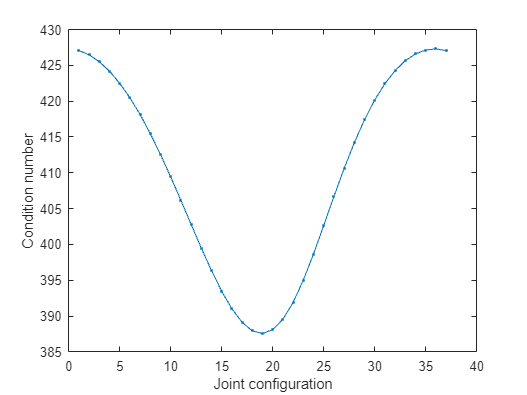

figure;
plot(k,'.-')
xlabel('Joint configuration')
ylabel('Condition number')

disp('Can be seen that the configuration is far from reaching singularity since the')

Can be seen that the configuration is far from reaching singularity since the


disp('condition number only reaches around 430 which is far from infinity')

condition number only reaches around 430 which is far from infinity


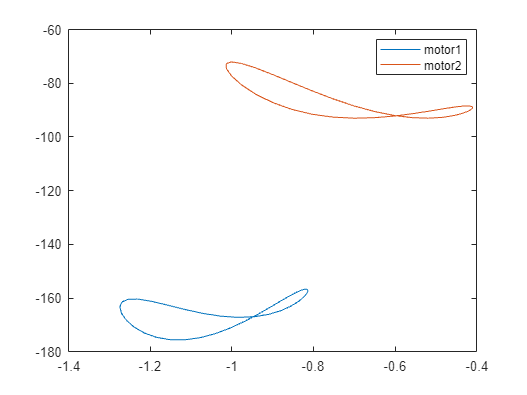

% this uses the collection of angles from problem 3
len = length(t1);
torque2 = zeros(1,len);
torque3 = zeros(1,len);
torque4 = zeros(1,len);

for i=1:len
    [torque2(i),torque3(i),torque4(i)] = torques(t2(i),t3(i),t4(i),1);
end

figure
plot(t2,torque2)
hold on

plot(t3,torque3)

%plot(t4,torque4)

legend(["motor1", "motor2"])%,"motor3"])


disp("Motor 4 is omitted here as the torques are smaller than")

Motor 4 is omitted here as the torques are smaller than


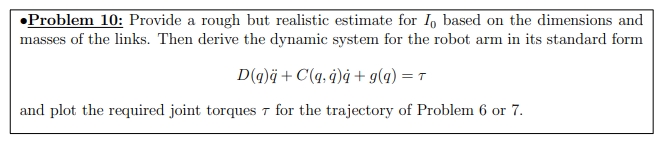

% For I0, we will approximate the intertia as a axbxc box. That is 
%   - Ixx = (m/12)*(b^2 + c^2)
%   - Iyy = (m/12)*(a^2 + c^2)
%   - Izz = (m/12)*(a^2 + b^2)
% We consider the mass as the mean of the masses of the links

m = mean([60,80,80,40]); % grams

% We see that I0 is defined as Ixx for link 1
I0 = (m/12)*(0.02^2);

% Inertia matrices
D1 = [I0 0 0; 0 0.4*I0 0; 0 0 0.9*I0];
D2 = [0.45*I0 0 0; 0 1.4*I0 0; 0 0 1.2*I0];
D3 = D2;
D4 = [0.5*I0 0 0; 0 0.5*I0 0; 0 0 0.5*I0];